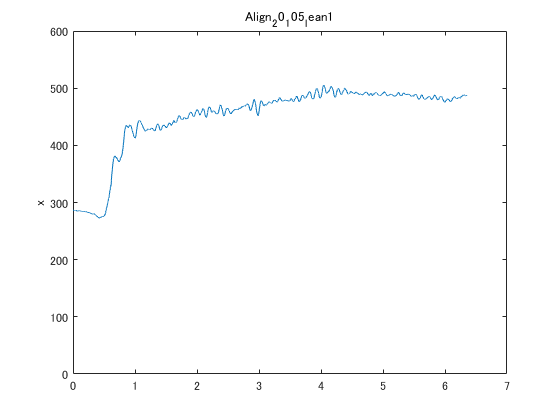

clear
%%
% plot force xz
filename = ['Align_105_0_3'];

FP_File = ['.\ex_210302\' filename '.forces']; %Foce_dataのファイル名
FP_data = (dlmread(FP_File,'	',5,1));

motion_file = ['.\ex_210302\' filename '.trc'];
M_data = (dlmread(motion_file,'	',6,2))/1000;

FX = FP_data(:,1)+FP_data(:,8)+FP_data(:,15)+FP_data(:,22);
FZ = FP_data(:,3)+FP_data(:,10)+FP_data(:,17)+FP_data(:,24);
xR = FP_data(:,11);
xL = FP_data(:,4);
FXR = FP_data(:,8);
FXL = FP_data(:,1);
FZR = FP_data(:,10);
FZL = FP_data(:,3);
mass = 88;
g = 9.8;
m1 = 2*1.1*mass*g/100; %足部
m2 = 2*5.4*mass*g/100; %下腿
m3 = 2*11*mass*g/100; %大腿
m4 = 48.9*mass*g/100; %体幹
m5 = 6.9*mass*g/100; %頭部
m6 = 2*0.6*mass*g/100; %手
m7 = 2*1.6*mass*g/100; %前腕
m8 = 2*2.7*mass*g/100; %上腕
a = zeros(length(FP_data(:,1)),1);
 for i = 1:length(FP_data(:,1))
     a(i,1) = i;
 end
 
time = a*0.0005;
 % {
 figure()
 plot(time, FX)
 ylim([0 600])
 ylabel('x')
 title('Align_20_105_lean1')
 hold off

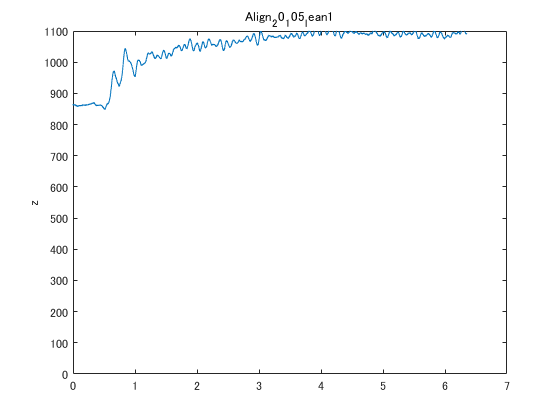

 
 figure()
 plot(time, FZ)
 ylim([0 1100])
 ylabel('z')
 title('Align_20_105_lean1')
 hold off

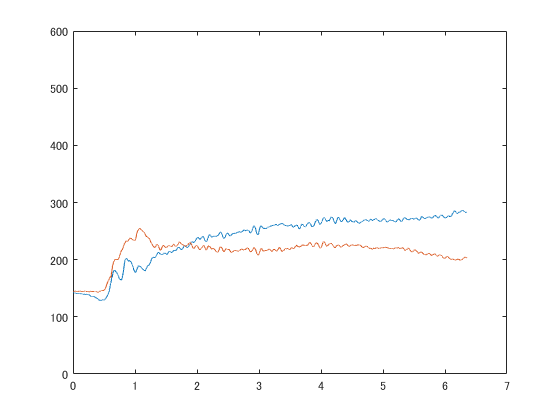

 
 figure()
 plot(time,FXR);
 ylim([0 600]);
 hold on;
 plot(time,FXL);
 hold off;

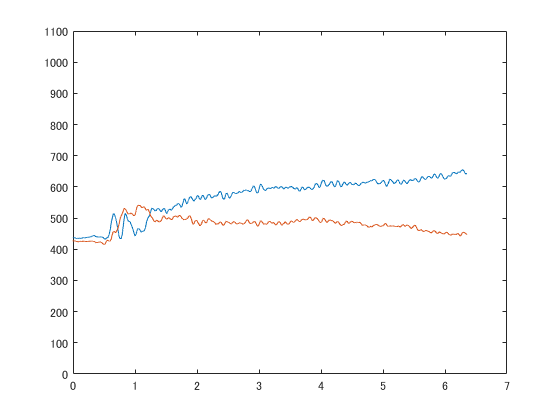

 
 figure()
 plot(time,FZR);
 ylim([0 1100]);
 hold on;
 plot(time,FZL);
 hold off;

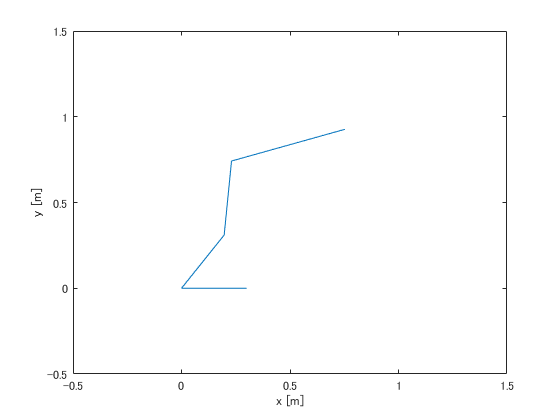

 %}
 
  
 F_force(:,1) = FXR+FXL;
 F_force(:,2) = FZR+FZL;
 F_force(:,3) = 0;
 
 [M,I] = max(F_force);
 F1(1) = F_force(11000,1);
 F1(2) = F_force(11000,2);
 F1(3) = F_force(11000,3);
 
 F2(1) = F1(1);
 F2(2) = F1(2) - m1;
 F2(3) = F1(3);
 
 F3(1) = F2(1);
 F3(2) = F2(2) - m2;
 F3(3) = F2(3);
 
 F4(1) = F3(1);
 F4(2) = F3(2) - m3;
 F4(3) = F3(3);
 
 Fout(1) = F4(1);
 Fout(2) = F4(2) - m4 - m5 - m6 - m7 - m8;
 Fout(3) = F4(3);

 
 %% 関節角度を求める
 
 

toe_heelL(:,1) = M_data(:,76) - M_data(:,85);
toe_heelL(:,2) = M_data(:,78) - M_data(:,87);
toe_heelR(:,1) = M_data(:,49) - M_data(:,58);
toe_heelR(:,2) = M_data(:,51) - M_data(:,60);


knee_ankleLO(:,1) = M_data(:,97) - M_data(:,91);
knee_ankleLO(:,2) = M_data(:,99) - M_data(:,93);
knee_ankleLI(:,1) = M_data(:,94) - M_data(:,88);
knee_ankleLI(:,2) = M_data(:,96) - M_data(:,90);
knee_ankleL = (knee_ankleLO + knee_ankleLI)./2;


knee_ankleRO(:,1) = M_data(:,70) - M_data(:,64);
knee_ankleRO(:,2) = M_data(:,72) - M_data(:,66);
knee_ankleRI(:,1) = M_data(:,67) - M_data(:,61);
knee_ankleRI(:,2) = M_data(:,69) - M_data(:,63);
knee_ankleR = (knee_ankleRO + knee_ankleRI)./2;


tro_kneeLO(:,1) = M_data(:,100) - M_data(:,97);
tro_kneeLO(:,2) = M_data(:,102) - M_data(:,99);
tro_kneeLI(:,1) = M_data(:,100) - M_data(:,94);
tro_kneeLI(:,2) = M_data(:,102) - M_data(:,96);
tro_kneeL = (tro_kneeLO + tro_kneeLI)./2;


tro_kneeRO(:,1) = M_data(:,73) - M_data(:,70);
tro_kneeRO(:,2) = M_data(:,75) - M_data(:,72);
tro_kneeRI(:,1) = M_data(:,73) - M_data(:,67);
tro_kneeRI(:,2) = M_data(:,75) - M_data(:,69);
tro_kneeR = (tro_kneeRO + tro_kneeRI)./2;


rib_APL(:,1) = M_data(:,121) - M_data(:,148);
rib_APL(:,2) = M_data(:,123) - M_data(:,150);
rib_APR(:,1) = M_data(:,118) - M_data(:,145);
rib_APR(:,2) = M_data(:,120) - M_data(:,147);


center_AS_PSL(:,1) = (M_data(:,133) + M_data(:,139))/2;
center_AS_PSL(:,2) = (M_data(:,135) + M_data(:,141))/2;
center_AS_PSR(:,1) = (M_data(:,130) + M_data(:,136))/2;
center_AS_PSR(:,2) = (M_data(:,132) + M_data(:,138))/2;
rib_ASPSL(:,1) = M_data(:,121) - center_AS_PSL(:,1);
rib_ASPSL(:,2) = M_data(:,123) - center_AS_PSL(:,2);
rib_ASPSR(:,1) = M_data(:,118) - center_AS_PSR(:,1);
rib_ASPSR(:,2) = M_data(:,120) - center_AS_PSR(:,2);


center_C7_clav(:,1) = (M_data(:,112) + M_data(:,115))/2;
center_C7_clav(:,2) = (M_data(:,114) + M_data(:,117))/2;
C7clav_AP(:,1) = center_C7_clav(:,1) - (M_data(:,145) + M_data(:,148))/2;
C7clav_AP(:,2) = center_C7_clav(:,2) - (M_data(:,147) + M_data(:,150))/2;

C7clav_ASPS(:,1) = center_C7_clav(:,1) - (center_AS_PSL(:,1) + center_AS_PSR(:,1))/2;
C7clav_ASPS(:,2) = center_C7_clav(:,2) - (center_AS_PSL(:,2) + center_AS_PSR(:,2))/2;

c7clav_tro(:,1) = center_C7_clav(:,1) - (M_data(:,73)+M_data(:,100))/2;
c7clav_tro(:,2) = center_C7_clav(:,2) - (M_data(:,75)+M_data(:,102))/2;

toe_heel = (toe_heelR + toe_heelL)./2;
knee_ankle = (knee_ankleR + knee_ankleL)./2;
tro_knee = (tro_kneeR + tro_kneeL)./2;
rib_AP = (rib_APR + rib_APL)./2;
rib_ASPS = (rib_ASPSL + rib_ASPSR)./2;


result_exp = zeros(length(toe_heel(:,1)),7);

for i = 1:length(toe_heel(:,1))
    norm_toe_heel = norm(toe_heel(i,:));
    norm_knee_ankle = norm(knee_ankle(i,:));
    norm_tro_knee = norm(tro_knee(i,:));
    norm_rib_AP = norm(rib_AP(i,:));
    norm_rib_ASPS = norm(rib_ASPS(i,:));
    norm_C7clav_AP = norm(C7clav_AP(i,:));
    norm_C7clav_ASPS = norm(C7clav_ASPS(i,:));
    norm_c7clav_tro = norm(c7clav_tro(i,:));
    
    dot_toe_to_knee = dot(toe_heel(i,:),knee_ankle(i,:));
    dot_ankle_to_tro = dot(knee_ankle(i,:),tro_knee(i,:));
    dot_knee_to_rib = dot(tro_knee(i,:),rib_AP(i,:));
    dot_knee_to_rib2 = dot(tro_knee(i,:),rib_ASPS(i,:)); 
    dot_knee_to_C7clavAP = dot(tro_knee(i,:),C7clav_AP(i,:));
    dot_knee_to_C7clavASPS = dot(tro_knee(i,:),C7clav_ASPS(i,:));
    dot_knee_to_c7clavtro = dot(tro_knee(i,:),c7clav_tro(i,:));
    
    thin_angle = acos(dot_toe_to_knee/(norm_toe_heel*norm_knee_ankle));
    knee_angle = acos(dot_ankle_to_tro/(norm_knee_ankle*norm_tro_knee));
    hip_angle = acos(dot_knee_to_rib/(norm_tro_knee*norm_rib_AP));
    hip_angle2 = acos(dot_knee_to_rib/(norm_tro_knee*norm_rib_ASPS)); 
    hip_angle3 = acos(dot_knee_to_C7clavAP/(norm_tro_knee*norm_C7clav_AP));
    hip_angle4 = acos(dot_knee_to_C7clavASPS/(norm_tro_knee*norm_C7clav_ASPS));
    hip_angle5 = acos(dot_knee_to_c7clavtro/(norm_tro_knee*norm_c7clav_tro));
    
    result_exp(i,1) = thin_angle;
    result_exp(i,2) = knee_angle;
    result_exp(i,3) = hip_angle;
    result_exp(i,4) = hip_angle2;
    result_exp(i,5) = hip_angle3;
    result_exp(i,6) = hip_angle4;
    result_exp(i,7) = hip_angle5;
    
end

result_exp = rad2deg(result_exp);
result_experiment = array2table(result_exp,"VariableNames",{'thin_angle','knee_angle','hip_angle','hip_angle2','hip_angle3','hip_angle4','hip_angle5'});

% torque


syms x;


%%
%各セグメントの位置
row_foot(:,1) = (xL+xR)/2000;
row_foot(:,2) = 0;
row_foot(:,3) = 0;
r1_exp = row_foot(11000,:); %足圧中心

row_toe(:,1) = (M_data(:,49)+M_data(:,76))/2;
row_toe(:,2) = (M_data(:,51)+M_data(:,78))/2;
row_toe(:,3) = 0;
r10_exp = row_toe(1100,:); %つま先

row_heel(:,1) = (M_data(:,58)+M_data(:,85))/2;
row_heel(:,2) = (M_data(:,60)+M_data(:,87))/2;
row_heel(:,3) = 0;
r11_exp = row_heel(1100,:); %踵

row_ankle(:,1) = ((M_data(:,61)+M_data(:,64))/2 + (M_data(:,88)+M_data(:,91))/2)/2;
row_ankle(:,2) = ((M_data(:,63)+M_data(:,66))/2 + (M_data(:,90)+M_data(:,93))/2)/2;
row_ankle(:,3) = 0;
r2_exp = row_ankle(1100,:); %くるぶし


row_knee(:,1) = ((M_data(:,67)+M_data(:,70))/2 + (M_data(:,94)+M_data(:,97))/2)/2;
row_knee(:,2) = ((M_data(:,69)+M_data(:,72))/2 + (M_data(:,96)+M_data(:,99))/2)/2;
row_knee(:,3) = 0;
r3_exp= row_knee(1100,:); %膝


row_tro(:,1) = (M_data(:,73)+M_data(:,100))/2;
row_tro(:,2) = (M_data(:,75)+M_data(:,102))/2;
row_tro(:,3) = 0;
r4_exp = row_tro(1100,:); %大転子


row_neck(:,1) = (M_data(:,112)+M_data(:,115))/2;
row_neck(:,2) = (M_data(:,114)+M_data(:,117))/2;
row_neck(:,3) = 0;
r5_exp = row_neck(1100,:); %首

row_hand(:,1) = (M_data(:,1)+M_data(:,25))/2;
row_hand(:,2) = (M_data(:,3)+M_data(:,27))/2;
row_hand(:,3) = 0;
r7_exp = row_hand(1100,:); %手

row_forearm(:,1) = (M_data(:,4)+M_data(:,7)+M_data(:,28)+M_data(:,31))/4;
row_forearm(:,2) = (M_data(:,6)+M_data(:,9)+M_data(:,30)+M_data(:,33))/4;
row_forearm(:,3) = 0;
r8_exp = row_forearm(1100,:); %手首

row_upperarm(:,1) = (M_data(:,10)+M_data(:,13)+M_data(:,31)+M_data(:,34))/4;
row_upperarm(:,2) = (M_data(:,12)+M_data(:,15)+M_data(:,33)+M_data(:,36))/4;
row_upperarm(:,3) = 0;
r9_exp = row_upperarm(1100,:); %肘

row_head(:,1) = M_data(:,103);
row_head(:,2) = M_data(:,105);
row_head(:,3) = 0;
r6_exp = row_head(1100,:); %頭


%%
%%重心



r5_r4 = r5_exp - r4_exp;
rad_exp = atan(r5_r4(2)/r5_r4(1));
%%
%体幹のみ考慮
%{
r1g_exp = r10_exp*0.404+r9_exp*0.596; %足
r2g_exp = r2_exp*0.423+r3_exp*0.577; %下腿
r3g_exp = r3_exp*0.481+r4_exp*0.519; %大腿
r4g_exp = r4_exp*0.492+r5_exp*0.508; %体幹
T1 = [0,0,0];
T2 = cross(r2_exp-r1g_exp,-F2)+cross(r1_exp-r1g_exp,F1)+T1;
T3 = cross(r3_exp-r2g_exp,-F3)+cross(r2_exp-r2g_exp,F2)+T2;
T4 = cross(r4_exp-r3g_exp,-F4)+cross(r3_exp-r3g_exp,F3)+T3;
r5_true = r4_exp + [x*cos(rad_exp),x*sin(rad_exp),0];
real_x = cross([r4_exp(1)+x*cos(rad_exp),r4_exp(2)+x*sin(rad_exp),0]-r4g_exp,-Fout-m5-m6-m7-m8) + cross(r4_exp-r4g_exp,F4) + T4;
l4_real = double(solve(real_x(3)==0,x));
r5_real = r4_exp +[l4_real*cos(rad_exp),l4_real*sin(rad_exp),0];
%}

%体幹、頭部考慮
%{
r1g_exp = r10_exp*0.404+r9_exp*0.596; %足
r2g_exp = r2_exp*0.423+r3_exp*0.577; %下腿
r3g_exp = r3_exp*0.481+r4_exp*0.519; %大腿
r4g_exp = ((r4_exp*0.492+r5_exp*0.508)*(m4+m6+m7+m8)+(r5_exp*0.179+r6_exp*0.821)*m5)/(m4+m5+m6+m7+m8); %体幹
T1 = [0,0,0];
T2 = cross(r2_exp-r1g_exp,-F2)+cross(r1_exp-r1g_exp,F1)+T1;
T3 = cross(r3_exp-r2g_exp,-F3)+cross(r2_exp-r2g_exp,F2)+T2;
T4 = cross(r4_exp-r3g_exp,-F4)+cross(r3_exp-r3g_exp,F3)+T3;
r5_true = r4_exp + [x*cos(rad_exp),x*sin(rad_exp),0];
real_x = cross([r4_exp(1)+x*cos(rad_exp),r4_exp(2)+x*sin(rad_exp),0]-r4g_exp,-Fout) + cross(r4_exp-r4g_exp,F4) + T4;
l4_real = double(solve(real_x(3)==0,x));
r5_real = r4_exp +[l4_real*cos(rad_exp),l4_real*sin(rad_exp),0];
%}

%体幹、腕部、頭部考慮
% {
r1g_exp = r10_exp*0.404+r11_exp*0.596; %足
r2g_exp = r2_exp*0.423+r3_exp*0.577; %下腿
r3g_exp = r3_exp*0.481+r4_exp*0.519; %大腿
r4g_exp = ((r4_exp*0.492+r5_exp*0.508)*(m4)+(r5_exp*0.179+r6_exp*0.821)*m5+(r5_exp*0.471+r9_exp*0.529)*m8+(r9_exp*0.585+r8_exp*0.415)*m7+(r8_exp*0.109+r7_exp*0.891)*m6)/(m4+m5+m6+m7+m8); %体幹
T1_exp = [0,0,0];
T2_exp = cross(r2_exp-r1g_exp,-F2)+cross(r1_exp-r1g_exp,F1)+T1_exp;
T3_exp = cross(r3_exp-r2g_exp,-F3)+cross(r2_exp-r2g_exp,F2)+T2_exp;
T4_exp = cross(r4_exp-r3g_exp,-F4)+cross(r3_exp-r3g_exp,F3)+T3_exp;
r5_true = r4_exp + [x*cos(rad_exp),x*sin(rad_exp),0];
T4_gyaku = cross(r5_exp-r4g_exp,-Fout) + cross(r4_exp-r4g_exp,F4);



%}

rg_exp = (r1g_exp*m1+r2g_exp*m2+r3g_exp*m3+r4g_exp*m4)/(m1+m2+m3+m4);
rg_deg_exp = rad2deg(rg_exp(2)/rg_exp(1));




rad_deg = rad2deg(rad_exp);


l1 = norm(r10_exp-r11_exp);
l2 = norm(r3_exp-r2_exp);
l3 = norm(r4_exp-r3_exp);
l4 = norm(r5_exp-r4_exp);



r_vec_exp = r5_exp-r3_exp;
r_deg_exp = rad2deg(atan(r_vec_exp(2)/r_vec_exp(1)));


c7_clav_knee(:,1) = center_C7_clav(:,1) - (M_data(:,94)+M_data(:,97)+M_data(:,67)+M_data(:,70))/4;
c7_clav_knee(:,2) = center_C7_clav(:,2) - (M_data(:,96)+M_data(:,99)+M_data(:,69)+M_data(:,72))/4;
c7_clav_knee = [c7_clav_knee(1100,:) 0];
r_knee(:,1) = (M_data(:,94)+M_data(:,97)+M_data(:,67)+M_data(:,70))/4;
r_knee(:,2) = (M_data(:,96)+M_data(:,99)+M_data(:,69)+M_data(:,72))/4;
r_knee = [r_knee(1100,:) 0];
r3g_knee = r3g_exp - r_knee;
r4g_knee = r4g_exp - r_knee;
T3_calc = cross(c7_clav_knee,-Fout)+cross(r3g_knee,[0 -m3 0])+cross(r4g_knee,[0 -m4 0]);
 

syms X Y r theta real;

l = 1;
result_roop = zeros(200*200,8);

theta1_exp = deg2rad(result_exp(1100,1));
theta2_exp = deg2rad(result_exp(1100,2));
theta3_exp = deg2rad(-result_exp(1100,6));


figure(1)
plot([l1,0,l2*cos(theta1_exp),l2*cos(theta1_exp)+l3*cos(theta1_exp+theta2_exp)...
    ,l2*cos(theta1_exp)+l3*cos(theta1_exp+theta2_exp)+l4*...
    cos(theta1_exp+theta2_exp+theta3_exp)],...
    [0,0,l2*sin(theta1_exp),l2*sin(theta1_exp)+l3*sin(theta1_exp+theta2_exp)...
    ,l2*sin(theta1_exp)+l3*sin(theta1_exp+theta2_exp)+l4*...
    sin(theta1_exp+theta2_exp+theta3_exp)]);
xlim([-0.5,1.5]);
ylim([-0.5,1.5]);
xlabel('x [m]');
ylabel('y [m]');
hold off





syms T1 T2 T3 T4 T5 real;
syms theta1 theta2 theta3 theta4 theta Theta theta_ellip real;


syms g real;
syms F0gx F0gy F1gx F1gy F2gx F2gy F3gx F3gy real;
syms T_ank T_knee T_hip real;
syms x y fx fy X Y X_e Y_e r real;



% 各関節位置と部分質量中心 r1:つま先 r2:足首 r3:膝 r4:大転子 r5:首
heel = r11_exp;

r1 = r10_exp;
r2 = r2_exp;
r3 = r2+[l2*cos(theta1) l2*sin(theta1) 0 ];
r4 = r3 + [l3*cos(theta1+theta2) l3*sin(theta1+theta2) 0];
r5 = r4 + [l4*cos(theta1+theta2+theta3) l4*sin(theta1+theta2+theta3) 0];
l1g = heel + [l1*0.415 0 0];
l2g = r3*0.577 + r2*0.423;
l3g = r4*0.519 + r3*0.481;
l4g = (r5-r4)/2 + r4;

J_l2g = [diff(l2g(1),theta1),diff(l2g(1),theta2),diff(l2g(1),theta3);...
         diff(l2g(2),theta1),diff(l2g(2),theta2),diff(l2g(2),theta3)]

$$J\_l2g = \left(\begin{array}{ccc} -\frac{3820574374158017741\,\sin\left(\theta_{1}\right)}{18014398509481984000} & 0 & 0\\ \frac{3820574374158017741\,\cos\left(\theta_{1}\right)}{18014398509481984000} & 0 & 0 \end{array}\right)$$


J_l3g = [diff(l3g(1),theta1),diff(l3g(1),theta2),diff(l3g(1),theta3);...
         diff(l3g(2),theta1),diff(l3g(2),theta2),diff(l3g(2),theta3)]

$$J\_l3g = \left(\begin{array}{ccc} -\frac{2022408333436603719\,\sin\left(\theta_{1}+\theta_{2}\right)}{9007199254740992000}-\frac{6621446055733133\,\sin\left(\theta_{1}\right)}{18014398509481984} & -\frac{2022408333436603719\,\sin\left(\theta_{1}+\theta_{2}\right)}{9007199254740992000} & 0\\ \frac{2022408333436603719\,\cos\left(\theta_{1}+\theta_{2}\right)}{9007199254740992000}+\frac{6621446055733133\,\cos\left(\theta_{1}\right)}{18014398509481984} & \frac{2022408333436603719\,\cos\left(\theta_{1}+\theta_{2}\right)}{9007199254740992000} & 0 \end{array}\right)$$

     
J_l4g = [diff(l4g(1),theta1),diff(l4g(1),theta2),diff(l4g(1),theta3);...
         diff(l4g(2),theta1),diff(l4g(2),theta2),diff(l4g(2),theta3)]     

$$J\_l4g = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{1}-\frac{3896740526852801\,\sin\left(\theta_{1}+\theta_{2}\right)}{9007199254740992}-\frac{6621446055733133\,\sin\left(\theta_{1}\right)}{18014398509481984} & -\sigma_{1}-\frac{3896740526852801\,\sin\left(\theta_{1}+\theta_{2}\right)}{9007199254740992} & -\sigma_{1}\\ \sigma_{2}+\frac{3896740526852801\,\cos\left(\theta_{1}+\theta_{2}\right)}{9007199254740992}+\frac{6621446055733133\,\cos\left(\theta_{1}\right)}{18014398509481984} & \sigma_{2}+\frac{3896740526852801\,\cos\left(\theta_{1}+\theta_{2}\right)}{9007199254740992} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4990123766064983\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{18014398509481984}\\ \sigma_{2}=\frac{4990123766064983\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{18014398509481984} \end{array}$$


F2g = [0; -m2]

F2g =          0
  -93.1392


F3g = [0; -m3]

F3g =          0
 -189.7280


F4g = [0; -m4-m5-m6-m7-m8];

T_l2 = J_l2g.'*F2g

$$T\_l2 = \left(\begin{array}{c} -\frac{55600818867121632184773\,\cos\left(\theta_{1}\right)}{2814749767106560000000}\\ 0\\ 0 \end{array}\right)$$

T_l3 = J_l3g.'*F3g

$$T\_l3 = \left(\begin{array}{c} -\frac{11990859008945623449951\,\cos\left(\theta_{1}+\theta_{2}\right)}{281474976710656000000}-\frac{39258553664441745557\,\cos\left(\theta_{1}\right)}{562949953421312000}\\ -\frac{11990859008945623449951\,\cos\left(\theta_{1}+\theta_{2}\right)}{281474976710656000000}\\ 0 \end{array}\right)$$

T_l4 = J_l4g.'*F4g

$$T\_l4 = \left(\begin{array}{c} -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336}-\frac{9695582215563699649286450123515\,\cos\left(\theta_{1}+\theta_{2}\right)}{39614081257132168796771975168}-\frac{16474993440512872126336874986495\,\cos\left(\theta_{1}\right)}{79228162514264337593543950336}\\ -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336}-\frac{9695582215563699649286450123515\,\cos\left(\theta_{1}+\theta_{2}\right)}{39614081257132168796771975168}\\ -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336} \end{array}\right)$$


Tg = T_l2 + T_l3 + T_l4

$$Tg = \left(\begin{array}{c} -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336}-\frac{177861649932899440189954344934799827\,\cos\left(\theta_{1}+\theta_{2}\right)}{618970019642690137449562112000000}-\frac{1841028718693820944449630641094351571\,\cos\left(\theta_{1}\right)}{6189700196426901374495621120000000}\\ -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336}-\frac{177861649932899440189954344934799827\,\cos\left(\theta_{1}+\theta_{2}\right)}{618970019642690137449562112000000}\\ -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336} \end{array}\right)$$


T2g = Tg(1)

$$T2g = -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336}-\frac{177861649932899440189954344934799827\,\cos\left(\theta_{1}+\theta_{2}\right)}{618970019642690137449562112000000}-\frac{1841028718693820944449630641094351571\,\cos\left(\theta_{1}\right)}{6189700196426901374495621120000000}$$

T3g = Tg(2)

$$T3g = -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336}-\frac{177861649932899440189954344934799827\,\cos\left(\theta_{1}+\theta_{2}\right)}{618970019642690137449562112000000}$$

T4g = Tg(3)

$$T4g = -\frac{12416057704205726296208568239245\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{79228162514264337593543950336}$$



theta1 = theta1_exp;
theta2 = theta2_exp;
theta3 = theta3_exp;


%ヤコビアン

J =[- l3*sin(theta1 + theta2) - l2*sin(theta1) - l4*sin(theta1 + theta2 + theta3),...
    - l3*sin(theta1 + theta2) - l4*sin(theta1 + theta2 + theta3), ...
    -l4*sin(theta1 + theta2 + theta3);...
    l3*cos(theta1 + theta2) + l2*cos(theta1) + l4*cos(theta1 + theta2 +  theta3),...
    l3*cos(theta1 + theta2) + l4*cos(theta1 + theta2 + theta3),...
    l4*cos(theta1 + theta2 + theta3)]

J =    -0.9268   -0.6162   -0.1849
    0.7527    0.5561    0.5222




%ヤコビアンの逆行列の固有値Dと固有値ベクトルVを求める

% 力の固有値、固有値ベクトル
JJ = pinv(J.');
[V_Force,D_Force] = eig(J*J.');
Lambda_Force = [D_Force(1,1)^0.5,D_Force(2,2)^0.5];

% 速度の固有値、固有値ベクトル
[V_velosity,D_velosity] = eig(JJ*JJ.');
Lambda_Velosity = [D_velosity(1,1)^0.5,D_velosity(2,2)^0.5]

Lambda_Velosity =     0.6524    3.7231


V_vel1 = V_velosity(:,1)

V_vel1 =    -0.7261
    0.6875


V_vel2 = V_velosity(:,2)

V_vel2 =     0.6875
    0.7261



% トルクの固有値、固有値ベクトル
[V_Torque,D_Torque] = eig(JJ.'*JJ);
Lambda_Torque = [D_Torque(1,1)^0.5,D_Torque(2,2)^0.5,D_Torque(3,3)^0.5];
Lambda_1 = Lambda_Torque(1)

Lambda_1 = 0.0000e+00 + 8.3327e-09i

Lambda_2 = Lambda_Torque(2)

Lambda_2 = 0.6524

Lambda_3 = Lambda_Torque(3)

Lambda_3 = 3.7231

V_1 = V_Torque(:,1)

V_1 =     0.5319
   -0.8375
    0.1251


V_2 = V_Torque(:,2)

V_2 =     0.7767
    0.5414
    0.3219


V_3 = V_Torque(:,3)

V_3 =    -0.3373
   -0.0741
    0.9385


JJJ = pinv(JJ.');

%ヤコビアンの逆行列の確認
ans1 = JJ*J';
ans2 = J*JJ';


%出力される力

Fo = JJ*[T1;T2;T3];
Fx = Fo(1);
Fy = Fo(2);
the_m = matlabFunction(atan2(Fx,Fy));
F = -sqrt(Fx^2+Fy^2);


%足圧中心

rfootcenter = l1g;
F1 = [-fx, -fy+(m2+m3+m4+m5+m6+m7+m8), 0];
Fcop = [-fx, -fy+(m1+m2+m3+m4+m5+m6+m7+m8), 0];
rcop = [x 0 0];
Tcop = cross(rcop-rfootcenter,Fcop);
Tf = cross(r2-rfootcenter,-F1);
x = solve(Tcop(3)+Tf(3)-T_ank== 0,x);


%身体重心

rcenter = (rfootcenter*m1 + l2g*m2 + l3g*m3 + l4g*m4)/(m1+m2+m3+m4)

$$rcenter = \left(\begin{array}{ccc} \frac{37021050105832923203276226787673\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{229303288834324038702851847880704}+\frac{557181905562472529258420969163746183\,\cos\left(\theta_{1}+\theta_{2}\right)}{1791431944018156552366030061568000000}+\frac{2017820445973485940900985459332651053\,\cos\left(\theta_{1}\right)}{5971439813393855174553433538560000000}+\frac{79274682433811445785951083820733489}{157143152984048820382985093120000000} & \frac{37021050105832923203276226787673\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{229303288834324038702851847880704}+\frac{557181905562472529258420969163746183\,\sin\left(\theta_{1}+\theta_{2}\right)}{1791431944018156552366030061568000000}+\frac{2017820445973485940900985459332651053\,\sin\left(\theta_{1}\right)}{5971439813393855174553433538560000000}+\frac{1482417398971217504436005594342025409}{14331455552145252418928240492544000000} & 0 \end{array}\right)$$


%各関節トルクの上限

T1max = 400;
T1min = -100;
T2max =250;
T2min =-350;
T3max = 600;
T3min = -220;

Fm = matlabFunction(F,'Vars',{[T1,T2,T3]});


T2g = double(subs(T2g))

T2g = -329.3381

T3g = double(subs(T3g))

T3g = -170.2029

T4g = double(subs(T4g))

T4g = -147.7238

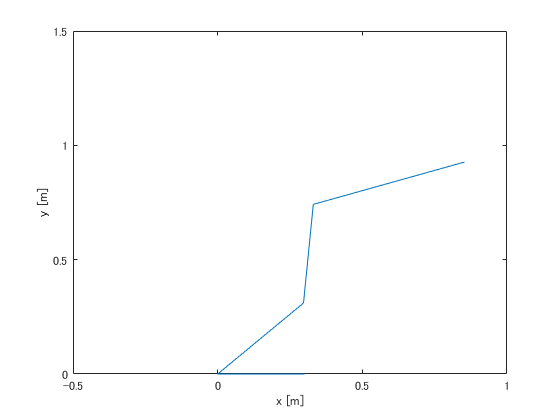

%姿勢図

figure(1)
plot([l1,0,0.1+l2*cos(theta1),0.1+l2*cos(theta1)+l3*cos(theta1+theta2)...
    ,0.1+l2*cos(theta1)+l3*cos(theta1+theta2)+l4*...
    cos(theta1+theta2+theta3)],...
    [0,0,l2*sin(theta1),l2*sin(theta1)+l3*sin(theta1+theta2)...
    ,l2*sin(theta1)+l3*sin(theta1+theta2)+l4*...
    sin(theta1+theta2+theta3)]);
xlim([-0.5,1]);
ylim([0,1.5]);
xlabel('x [m]');
ylabel('y [m]');
hold off


T_l2 = double(subs(T_l2))

T_l2 =   -10.5686
         0
         0


T_l3 = double(subs(T_l3))

T_l3 =   -40.6438
   -3.3326
         0


T_l4 = double(subs(T_l4))

T_l4 =  -278.1257
 -166.8704
 -147.7238



%aで関節トルクの変化量を決定

a = 3;
m = (round(T1min/-a) + round(T1max/a) +3)*(round(T2min/-a) + round(T2max/a))*(round(T3min/-a) + round(T3max/a));
n = 17;
result = zeros(m,n);
i = 1;

if (V_vel1(1) >= 0 && V_vel1(2) >= 0) || (V_vel1(1)<0 && V_vel1(2)<0)
    V_v(1) = abs(V_vel1(1));
    V_v(2) = abs(V_vel1(2));
    L_va = Lambda_Velosity(1);
    L_vb = Lambda_Velosity(2);
else
    V_v(1) = abs(V_vel2(1));
    V_v(2) = abs(V_vel2(2));
    L_va = Lambda_Velosity(2);
    L_vb = Lambda_Velosity(1);    
end

Theta = rad2deg(acos(V_v(1)/1));

f = ((X*cos(Theta)+Y*sin(Theta))^2)/L_va^2+((-X*sin(Theta)+Y*cos(Theta))^2)/L_vb^2-1 == 0

$$f = \frac{35184372088832\,{\left(\frac{3816304869814265\,X}{4503599627370496}-\frac{4782562804306325\,Y}{9007199254740992}\right)}^{2}}{487710799156665}+\frac{2251799813685248\,{\left(\frac{4782562804306325\,X}{9007199254740992}+\frac{3816304869814265\,Y}{4503599627370496}\right)}^{2}}{958510986280501}-1=0$$


X = r*cos(theta);
Y = r*sin(theta);
f = subs(f)

$$f = \frac{35184372088832\,{\left(\frac{3816304869814265\,r\,\cos\left(\theta \right)}{4503599627370496}-\frac{4782562804306325\,r\,\sin\left(\theta \right)}{9007199254740992}\right)}^{2}}{487710799156665}+\frac{2251799813685248\,{\left(\frac{4782562804306325\,r\,\cos\left(\theta \right)}{9007199254740992}+\frac{3816304869814265\,r\,\sin\left(\theta \right)}{4503599627370496}\right)}^{2}}{958510986280501}-1=0$$

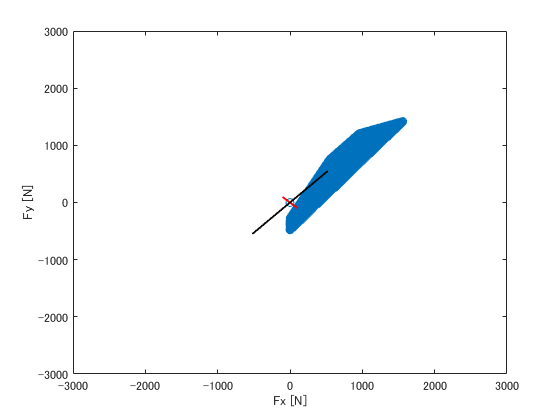




%固有値ベクトルをもとにトルクを求め、そこから出力される力を求める

for s = -250:a:550
    for t = -600:a:150
        T = s*V_2+t*V_3;
        T_ank = -(T(1)+T_l2(1)+T_l3(1)+T_l4(1));
        T_knee = -(T(2)+T_l2(2)+T_l3(2)+T_l4(2));
        T_hip = -(T(3)+T_l2(3)+T_l3(3)+T_l4(3));
        fx = subs(Fx,{T1,T2,T3},{T(1),T(2),T(3)});
        fy = subs(Fy,{T1,T2,T3},{T(1),T(2),T(3)});
        xx = subs(x);
        F_cop = subs(Fcop);
       
        result(i,12) = s;
        result(i,13) = t;
        if  (T1min < T_ank) &&...
           (T_ank < T1max) && (T2min < T_knee) && (T_knee < T2max) &&...
           (T3min < T_hip) && (T_hip < T3max) && fx<0 && (heel(1)<xx) && (xx < r1(1))
               
        if T_ank>=0
            ra_T1 = T_ank/(T1max)*100;
            
        else
            ra_T1 = T_ank/(T1min)*100;
        
        end
        if T_knee>= 0
            ra_T2 = T_knee/(T2max)*100;
        else
            ra_T2 = T_knee/(T2min)*100;
        end
        if T_hip >= 0
            ra_T3 = T_hip/(T3max)*100;
        else
            ra_T3 = T_hip/(T3min)*100;
        end
            result(i,7) = -fx; 
            result(i,1) = T_ank;
            result(i,2) = ra_T1;
            result(i,3) = T_knee;
            result(i,4) = ra_T2;
            result(i,5) = T_hip;
            result(i,6) = ra_T3;
            result(i,14) = F_cop(1);
            result(i,15) = F_cop(2);
            result(i,11) = xx*100;
            result(i,8) = -fy;
            result(i,9) = sqrt(fx^2+fy^2);
            result(i,10) = (ra_T1+ra_T2+ra_T3)/3;
            theta = rad2deg(atan(fy/fx));
            result(i,17) = theta;

            

        else

        end
        

            

            i = i+1;
    end
end
result_Table_test = array2table(result,"VariableNames",{'T_ank','%T_ank','T_knee','%T_knee','T_hip','%T_hip','Fx','Fy','F','avg','cop_x','s','t','F_copx','F_copy','power_fy','theta'});

figure(2)
plot(result(:,7),result(:,8),'o');
hold on;
xlim([-3000 3000]);
ylim([-3000 3000]);
xlabel('Fx [N]');
ylabel('Fy [N]');


%各固有値ベクトルの方向（赤：短軸、黒：長軸）

for s = -200:4:200
    T = s*V_2;
    T1 = T(1);
    T2 = T(2);
    T3 = T(3);
    fx1 = subs(Fx);
    fy1 = subs(Fy);
    plot(fx1,fy1,'r-o','MarkerSize',1,'MarkerFaceColor',[1,0,0])
end

for t = -200:2:200
    T = t*V_3;
    T1 = T(1);
    T2 = T(2);
    T3 = T(3);
    fx2 = subs(Fx);
    fy2 = subs(Fy);
    plot(fx2,fy2,'k-o','MarkerSize',1,'MarkerFaceColor',[0,0,0])
end
hold off